## Power Flow

clc
clear all; close all;
cd("C:\Users\athul.p\Documents\GitHub\Power_System_Dynamics\HW6")
% cd("C:\Users\athul.p\Documents\GitHub\PowerSystemDynamic")
% Initializing Kundur 2 area system and importing data
n_bus = 11;
bus_data = importdata('ieee11bus.txt').data;
% bus_data = importdata('ieee11bus_allPV.txt').data;
branch_data = importdata('ieee11branch.txt').data;
   
% Ybus formation
t = 0; % 0 for without tap, 1 for with tap
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% Scheduled power calculation
base_MVA = 100;
P_inj = (bus_data(:,8) - bus_data(:,6)) / base_MVA;
Q_inj = (bus_data(:,9) - bus_data(:,7)) / base_MVA;

% Finding bus types
pv_i = find(bus_data(:,3) == 2);
pq_i = find(bus_data(:,3) == 0);
n_pv = length(pv_i);
n_pq = length(pq_i);

% Initializing Voltage magnitude and angles
V = bus_data(:,11);
V(V(:)==0) = 1;
T = zeros(n_bus,1);

% Newton Raphson Method
[V1_data,T1_data,T1] = NR(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);
% V = V1_data(:,end)
% T = T1_data(:,end)

% Fast Decoupled Mehod
%[V2_data,T2_data,T2] = FD(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);

% P,Q calculation after convergence
[P,Q] = PQ_calc(V1_data(:,size(V1_data,2)),T1_data(:,size(T1_data,2)),Y);
V = V1_data(:,size(V1_data,2));
T = T1_data(:,size(T1_data,2));
% [P,Q] = PQ_calc(V,T,Y)

% plotting convergence curves
% mplot([1:size(V1_data,2)],T1,[1:size(V1_data,2)],T1)

bus_data = importdata('ieee11bus_ynet.txt').data;
branch_data = importdata('ieee11branch_ynet.txt').data;
t = 0; % 0 for without tap, 1 for with tap
n_bus = 14;
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% calculating Ygen matrix

Y_gen = Y_gen_calc(Y)

Y_gen =        3.1519 -     12.697i       1.5578 +     7.2405i       1.0648 +     1.5522i       1.5415 +     2.1172i
       1.5578 +     7.2405i        1.299 -     10.992i      0.75503 +    0.97052i        1.088 +     1.3202i
       1.0648 +     1.5522i      0.75503 +    0.97052i       1.5317 -     8.3645i       1.8025 +     3.9505i
       1.5415 +     2.1172i        1.088 +     1.3202i       1.8025 +     3.9505i       2.6612 -     10.228i



P_gen = P(2:4);
Q_gen = Q(2:4);
V(12:14) = V(2:4);
T(12:14) = T(2:4);

% calculating Igen
I_gen = (P_gen - i*Q_gen)./(V(12:14).*exp(-i*T(12:14)));

X_gen = (((0.3+0.55)/2)*base_MVA/900);

% calculating Egen
E = (V(12:14).*exp(i*T(12:14))) + (i*X_gen.*I_gen);
[Theta, E_g] = cart2pol(real(E),imag(E))

Theta =       0.15413
      0.11778
    -0.044049


E_g =        1.0844
        1.127
       1.0748


E_g = [V(1); E_g]

E_g =          1.03
       1.0844
        1.127
       1.0748


Theta = [T(1); Theta]

Theta =             0
      0.15413
      0.11778
    -0.044049


## Dynamic Initialization (Type 3)

t = sym('t', [1 3]);
w = sym('w', [1 3]);

F = type3(t, w, P_gen, Y_gen, E_g)

$$F = \left(\begin{array}{c} 120\,\pi \,\left(w_{1}-1\right)\\ 120\,\pi \,\left(w_{2}-1\right)\\ 120\,\pi \,\left(w_{3}-1\right)\\ \frac{422212149182881}{5488762045857792}-\frac{8979838330870109\,\cos\left(t_{3}-t_{1}+\frac{496266282224763}{562949953421312}\right)}{526921156402348032}-\frac{2442442535687225\,\cos\left(\frac{6544451178535127}{4503599627370496}\right)}{21955048183431168}-\frac{4656985993045987\,\cos\left(t_{1}-\frac{6119849204416963}{4503599627370496}\right)}{65865144550293504}-\frac{6768291313893709\,\cos\left(t_{2}-t_{1}+\frac{8193263697164983}{9007199254740992}\right)}{526921156402348032}-\frac{2\,w_{1}}{117}\\ \frac{25867545411767935}{312859436613894144}-\frac{647431341052205\,\cos\left(t_{2}-\frac{2183231722217033}{2251799813685248}\right)}{32932572275146752}-\frac{29610347515339745\,\cos\left(t_{3}-t_{2}+\frac{5146420777147135}{4503599627370496}\right)}{625718873227788288}-\frac{1689103418577295\,\cos\left(\frac{3129289356278847}{2251799813685248}\right)}{17381079811883008}-\frac{33841456569468545\,\cos\left(t_{1}-t_{2}+\frac{8193263697164985}{9007199254740992}\right)}{2502875492911153152}-\frac{40\,w_{2}}{2223}\\ \frac{6333181990779895}{78214859153473536}-\frac{44899191654350545\,\cos\left(t_{1}-t_{3}+\frac{3970130257798105}{4503599627370496}\right)}{2502875492911153152}-\frac{9870115838446585\,\cos\left(t_{2}-t_{3}+\frac{2573210388573567}{2251799813685248}\right)}{208572957742596096}-\frac{8160312667098365\,\cos\left(t_{3}-\frac{8479923707299357}{9007199254740992}\right)}{312859436613894144}-\frac{17181230072925125\,\cos\left(\frac{2963940509809101}{2251799813685248}\right)}{156429718306947072}-\frac{40\,w_{3}}{2223} \end{array}\right)$$

solVal0 = [0, 0, 0, 1, 1, 1]

solVal0 =      0     0     0     1     1     1


vars = [t, w];
vpa(F,3)

$$ans = \left(\begin{array}{c} 377.0\,w_{1}-377.0\\ 377.0\,w_{2}-377.0\\ 377.0\,w_{3}-377.0\\ 0.0639-0.0707\,\cos\left(t_{1}-1.36\right)-0.017\,\cos\left(t_{3}-1.0\,t_{1}+0.882\right)-0.0128\,\cos\left(t_{2}-1.0\,t_{1}+0.91\right)-0.0171\,w_{1}\\ 0.0652-0.0473\,\cos\left(t_{3}-1.0\,t_{2}+1.14\right)-0.0197\,\cos\left(t_{2}-0.97\right)-0.0135\,\cos\left(t_{1}-1.0\,t_{2}+0.91\right)-0.018\,w_{2}\\ 0.0533-0.0473\,\cos\left(t_{2}-1.0\,t_{3}+1.14\right)-0.0261\,\cos\left(t_{3}-0.941\right)-0.0179\,\cos\left(t_{1}-1.0\,t_{3}+0.882\right)-0.018\,w_{3} \end{array}\right)$$


sol = vpasolve(F == 0, vars, solVal0)

sol = struct with fields:
    t1: 0.15413780561398847267985638529707
    t2: 0.1178366462094189064397647195303
    t3: -0.043987884005915990696011754641505
    w1: 1.0
    w2: 1.0
    w3: 1.0


## Small Signal Stability (Type 3)

trans_init = [];
% making Jacobian
for i = 1:length(vars)
    sol_val{i} = sol.(char(vars(i)));
    trans_init = [trans_init double(sol.(char(vars(i))))];
end
J = jacobian(F, vars);

% substituting solution
J_val = subs(J, vars, sol_val)

$$J\_val = \left(\begin{array}{cccccc} 0 & 0 & 0 & 120\,\pi & 0 & 0\\ 0 & 0 & 0 & 0 & 120\,\pi & 0\\ 0 & 0 & 0 & 0 & 0 & 120\,\pi \\ -0.086626996116801148655277056914762 & 0.0098453481989559730664870346455522 & 0.010761209391209686856971711258813 & -\frac{2}{117} & 0 & 0\\ 0.01096616342526626004594748342611 & -0.065082898843310010665081235012974 & 0.039324883807621175452846768449917 & 0 & -\frac{40}{2223} & 0\\ 0.015818702483321907308046491080599 & 0.045654864862407244644693521390181 & -0.083214269120939333849758059485878 & 0 & 0 & -\frac{40}{2223} \end{array}\right)$$

J_val = double(J_val);

% eigen value and vectors
[r_ev, eig_val] = eig(J_val);
l_ev = inv(r_ev);

% participation factor
norm_p = []; 
for i = 1: length(vars)
    p_mat = r_ev(:,i)*l_ev(i,:);
    diag_vec = abs(diag(p_mat));
    norm_p = [norm_p diag_vec./max(diag_vec)];
end

% calculating mode frequency
eigen_frequency_mode= abs(imag(diag(eig_val)))/2/pi;
eigen = diag(eig_val);
100*(-real(eigen)./abs(eigen))

ans =        0.2842
       0.2842
      0.13482
      0.13482
       0.1469
       0.1469


## Transient Stability (Type 3)

% Ybus
Y_pre = Y;
Y_fault = y_fault_update();
Y_post = y_post_update();

% generating fault on system equations
Y_gen_fault = Y_gen_calc(Y_fault);
F_fault = type3(t, w, P_gen, Y_gen_fault, E_g);

% generating post fault system equations
Y_gen_post = Y_gen_calc(Y_post);
F_post = type3(t, w, P_gen, Y_gen_post, E_g);

% simulation parameters
h = 1e-3; Tf = 0; Tc = 7/60; Ts = 20;

% prefault scenario
x_init = trans_init;
x_step = [];
time_step = [];
[x_step, time_step] = Euler_step(h,x_init,F,vars,0,Tf-h);
x_data = [x_init' x_step];
time_data = [0 time_step];

% fault on scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_fault,vars,Tf,Tf+Tc);

0 seconds of simulation finished 


x_data = [x_data x_step];
time_data = [time_data time_step];

% post fault scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_post,vars,Tf+Tc+h,Ts);
x_data = [x_data x_step];
time_data = [time_data time_step];

% seperating theta and omega variables
t_data = x_data(1:3,:);
w_data = x_data(4:6,:);


ax =   Axes with properties:

             XLim: [0 20]
             YLim: [-1.0365 400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.14567 0.775 0.77933]
            Units: 'normalized'

  Show all properties


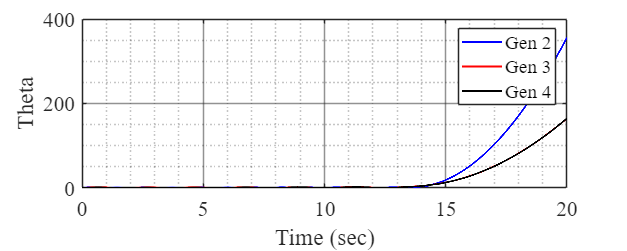


% plotting the graph
mplot(time_data, t_data, 'Theta')

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [0.95 1.3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.14567 0.775 0.77933]
            Units: 'normalized'

  Show all properties


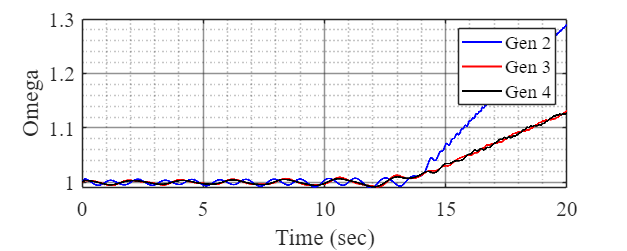

mplot(time_data, w_data, 'Omega')

## Dynamic Initialization (Type 2)

t = sym('t', [1 3]);
w = sym('w', [1 3]);
Eq = sym('Eq', [1 3]);
Ed = sym('Ed', [1 3]);
Efd = sym('Efd', [1 3]);
Pm = sym('Pm', [1 3]);
Vref = sym('Vref', [1 3]);
Pc = sym('Pc', [1 3]);
Vw = sym('Vw', [1 3]);
Vs = sym('Vs', [1 3]);



vars = [t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs];
F = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs, P_gen, Y_gen, E_g, V, T);

x0 = [0.685 0.614 0.504  1 1 1  0.935 0.991 0.916  0.549 0.537 0.559  1.845 1.935 1.813  7.013 7.204 7.013 1.019 1.040 1.019 7.013 7.204 7.013 1 1 1 1 1 1];
sol = vpasolve(F,vars,x0)

sol = struct with fields:
       t1: 0.73012362529581486256165616895831
       t2: 0.65687498444885528450083883200644
       t3: 0.54783652526147714040723013222078
       w1: 1.0
       w2: 1.0
       w3: 1.0
      Eq1: 0.90946682821947830178734386990396
      Eq2: 0.96718862358221783399424028803851
      Eq3: 0.8918971361929880372965194348014
      Ed1: 0.59064544965806176089004041491732
      Ed2: 0.57858391571923695576703439000213
      Ed3: 0.59964666892862622808488483236939
     Efd1: 1.7448315172209092988170499089702
     Efd2: 1.8294497080311120987883089458004
     Efd3: 1.7184269984839945372313141225833
      Pm1: 7.0001442751686934996605646472464
      Pm2: 7.1897445895520757915049018062202
      Pm3: 6.9992763992011340352558251273426
    Vref1: 1.0012758424138954535059147504551
    Vref2: 1.020852751459844439506058455271
    Vref3: 1.0014078650075800273138434293871
      Pc1: 7.0001442751686934996605646472464
      Pc2: 7.1897445895520757915049018062202
      Pc3: 6.999276399

## Small Signal Stability (Type 2)

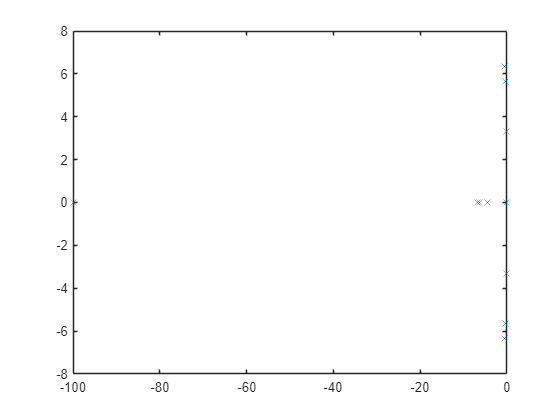

state_vars = [t, w, Eq, Ed, Efd, Pm];

% making Jacobian
J = jacobian(F(1:18), state_vars);
sol_val = {};
for i = 1:length(state_vars)
    sol_val{i} = sol.(char(state_vars(i)));
end

% substituting solution
J_val = subs(J, state_vars, sol_val);
J_val = double(J_val);

% eigen value and vectors
[r_ev, eig_val] = eig(J_val);
l_ev = inv(r_ev);

% participation factor
norm_p = []; 
for i = 1: length(state_vars)
    p_mat = r_ev(:,i)*l_ev(i,:);
    diag_vec = abs(diag(p_mat));
    norm_p = [norm_p diag_vec./max(diag_vec)];
end

% calculating mode frequency
eigen = diag(eig_val);
eigen_frequency_mode= abs(imag(eigen))/2/pi;
damping = 100*(-real(eigen)./abs(eigen));


figure()
plot(real(eigen),imag(eigen),"x")

## PSS Analysis


pss_vars = [t, w, Eq, Ed, Efd, Pm, Vw, Vs];
F = type2_pss(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs, P_gen, Y_gen, E_g, V, T);

sol = vpasolve(F,vars,x0)

sol = struct with fields:
       t1: 0.73012362529581486256165616895831
       t2: 0.65687498444885528450083883200644
       t3: 0.54783652526147714040723013222078
       w1: 1.0
       w2: 1.0
       w3: 1.0
      Eq1: 0.90946682821947830178734386990396
      Eq2: 0.96718862358221783399424028803851
      Eq3: 0.8918971361929880372965194348014
      Ed1: 0.59064544965806176089004041491732
      Ed2: 0.57858391571923695576703439000213
      Ed3: 0.59964666892862622808488483236939
     Efd1: 1.7448315172209092988170499089702
     Efd2: 1.8294497080311120987883089458004
     Efd3: 1.7184269984839945372313141225833
      Pm1: 7.0001442751686934996605646472464
      Pm2: 7.1897445895520757915049018062202
      Pm3: 6.9992763992011340352558251273426
    Vref1: 1.0012758424138954535059147504551
    Vref2: 1.020852751459844439506058455271
    Vref3: 1.0014078650075800273138434293871
      Pc1: 7.0001442751686934996605646472464
      Pc2: 7.1897445895520757915049018062202
      Pc3: 6.999276399

F_pss = [F(1:18);F(25:30)];

% making Jacobian
J = jacobian(F_pss, pss_vars);
sol_val = {};
for i = 1:length(pss_vars)
    sol_val{i} = sol.(char(pss_vars(i)));
end

% substituting solution
J_val = subs(J, pss_vars, sol_val);
J_val = double(J_val);

[r_ev, eig_val] = eig(J_val);
eigen_pss = diag(eig_val);
eigen_frequency_mode_pss= abs(imag(eigen_pss))/2/pi;
damping_pss = 100*(-real(eigen_pss)./abs(eigen_pss))

damping_pss =           100
          100
          100
          100
          100
          100
       9.4009
       9.4009
       8.0568
       8.0568


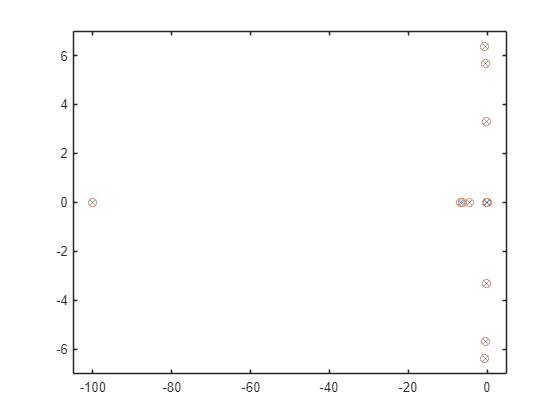


figure()

plot(real(eigen),imag(eigen),"x")
hold on
plot(real(eigen_pss),imag(eigen_pss),"o")

xlim([-105.0 5.0])
ylim([-7.0 7.0])

ax =   Axes with properties:

             XLim: [-105 5]
             YLim: [-7 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


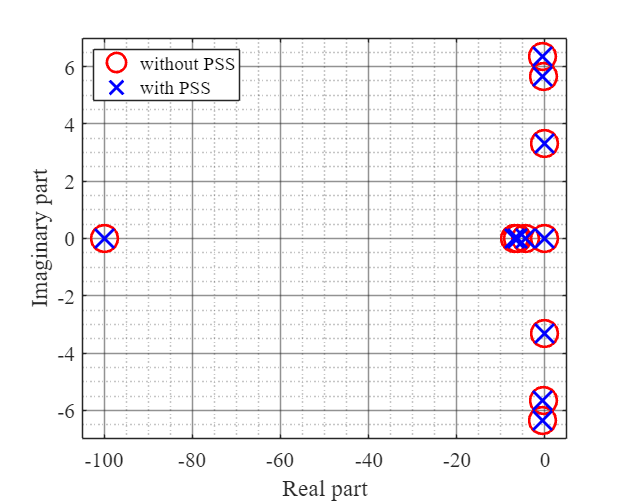


mplot_eigen(real(eigen),imag(eigen),real(eigen_pss),imag(eigen_pss))

## Transient Stability (Type 2)

F = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs, P_gen, Y_gen, E_g, V, T);

x0 = [0.685 0.614 0.504  1 1 1  0.935 0.991 0.916  0.549 0.537 0.559  1.845 1.935 1.813  7.013 7.204 7.013 1.019 1.040 1.019 7.013 7.204 7.013 1 1 1 1 1 1];
sol = vpasolve(F,vars,x0)

sol = struct with fields:
       t1: 0.73012362529581486256165616895831
       t2: 0.65687498444885528450083883200644
       t3: 0.54783652526147714040723013222078
       w1: 1.0
       w2: 1.0
       w3: 1.0
      Eq1: 0.90946682821947830178734386990396
      Eq2: 0.96718862358221783399424028803851
      Eq3: 0.8918971361929880372965194348014
      Ed1: 0.59064544965806176089004041491732
      Ed2: 0.57858391571923695576703439000213
      Ed3: 0.59964666892862622808488483236939
     Efd1: 1.7448315172209092988170499089702
     Efd2: 1.8294497080311120987883089458004
     Efd3: 1.7184269984839945372313141225833
      Pm1: 7.0001442751686934996605646472464
      Pm2: 7.1897445895520757915049018062202
      Pm3: 6.9992763992011340352558251273426
    Vref1: 1.0012758424138954535059147504551
    Vref2: 1.020852751459844439506058455271
    Vref3: 1.0014078650075800273138434293871
      Pc1: 7.0001442751686934996605646472464
      Pc2: 7.1897445895520757915049018062202
      Pc3: 6.999276399



trans_init = [];
for i = 1:length(vars)
    trans_init = [trans_init double(sol.(char(vars(i))))];
end


% generating fault on system equations
Y_gen_fault = Y_gen_calc(Y_fault);
F_fault = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs, P_gen, Y_gen_fault, E_g, V, T);

% generating post fault system equations
Y_gen_post = Y_gen_calc(Y_post);
F_post = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vs, P_gen, Y_gen_post, E_g, V, T);

% simulation parameters
h = 1e-3; Tf = 0; Tc = 6/60; Ts = 10;

x_step = [];
time_step = [];
% prefault scenario
x_init = trans_init;
[x_step, time_step] = Euler_step(h,x_init,F,vars,0,Tf-h);
x_data = [x_init' x_step];
time_data = [0 time_step];

% fault on scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_fault,vars,Tf,Tf+Tc);

0 seconds of simulation finished 


x_data = [x_data x_step];
time_data = [time_data time_step];

% post fault scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_post,vars,Tf+Tc+h,Ts);

1 seconds of simulation finished 
2 seconds of simulation finished 
3 seconds of simulation finished 
4 seconds of simulation finished 
5 seconds of simulation finished 
6 seconds of simulation finished 
7 seconds of simulation finished 
8 seconds of simulation finished 


x_data = [x_data x_step];
time_data = [time_data time_step];

% seperating theta and omega variables
t_data = x_data(1:3,:);
w_data = x_data(4:6,:);


ax =   Axes with properties:

             XLim: [0 12]
             YLim: [-6.1797e+22 3.8838e+07]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1457 0.7750 0.7768]
            Units: 'normalized'

  Show all properties


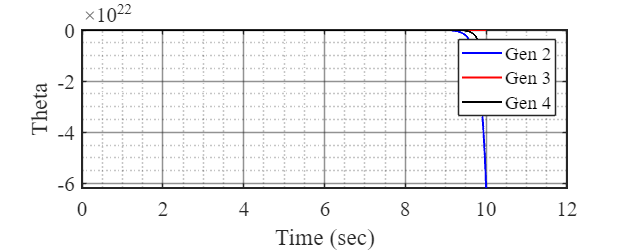

% plotting the graph
mplot(time_data, t_data, 'Theta')

ax =   Axes with properties:

             XLim: [0 12]
             YLim: [-1.2000e+21 2.0000e+20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1457 0.7750 0.7768]
            Units: 'normalized'

  Show all properties


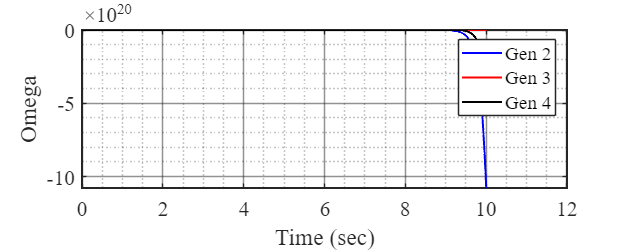

mplot(time_data, w_data, 'Omega')